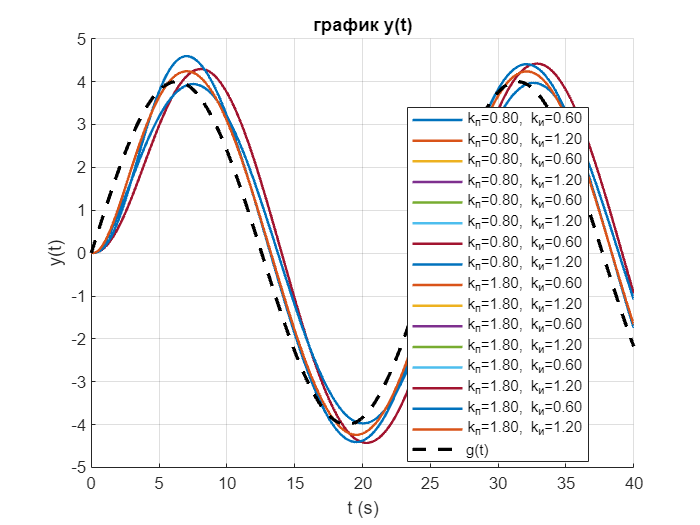


model    = 'ba5';   % <-- đổi tên model (không .slx)
stopTime = 40;
kp_list  = [0.8 0.8 1.8 1.8];
ki_list  = [0.6 1.2 0.6 1.2];

% Chọn g(t) tại đây (ví dụ: g(t)=1)
T = (0:0.001:stopTime).';
%g = T;               % <-- đổi thành 3*t, 0.5*t.^2 ... nếu muốn
g = 4*sin(0.25.*T);
g_signal = [T, g];               % dữ liệu cho From Workspace (Data = g_signal)

%% ===== Chuẩn bị mô phỏng =====
load_system(model);
set_param(model, 'StopTime', num2str(stopTime));

results = struct(); idx = 0;

for kp = kp_list
    for ki = ki_list
        idx = idx + 1;

        % Truyền tham số vào model qua SimulationInput
        assignin('base', 'kp', kp);
        assignin('base', 'ki', ki);

        % Chạy mô phỏng
        simOut = sim('ba5', 'ReturnWorkspaceOutputs', 'on');

        % Đọc y_out = [t y]
         y_struct = simOut.get('y_out');   % nếu biến khác tên, đổi ở đây
        t = y_struct.time;
        y = y_struct.signals.values;

        % Tính e(t) = g(t) - y(t) trên cùng lưới thời gian của y
        g_res = interp1(g_signal(:,1), g_signal(:,2), t, 'linear', 'extrap');
        e     = g_res - y;

        % Lưu
        results(idx).kP = kp;
        results(idx).kI = ki;
        results(idx).t  = t;
        results(idx).y  = y;
        results(idx).e  = e;
    end
end

%% ===== Vẽ y(t) trên cùng một trục =====
figure; hold on; grid on;
for i = 1:numel(results)
    plot(results(i).t, results(i).y, 'LineWidth', 1.5,  'DisplayName',...
        sprintf('k_п=%.2f, k_и=%.2f', results(i).kP, results(i).kI));
end
plot(t, g, '--', 'LineWidth', 2, 'Color', 'black', 'DisplayName','g(t)');   % vẽ tín hiệu đặt
xlabel('t (s)'); ylabel('y(t)');
title('график y(t)');
legend('Location','best');

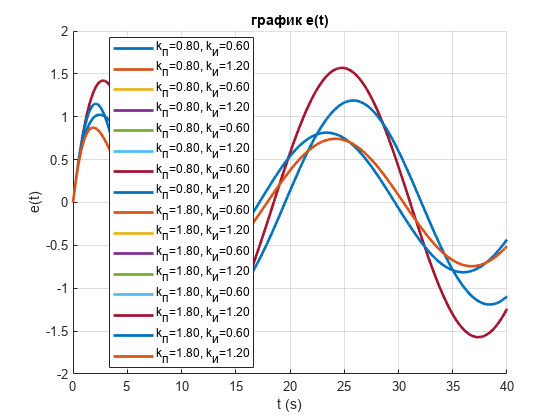


%% ===== Vẽ e(t) trên cùng một trục =====
figure; hold on; grid on;
for i = 1:numel(results)
    plot(results(i).t, results(i).e, 'LineWidth', 2, 'DisplayName', ...
        sprintf('k_п=%.2f, k_и=%.2f', results(i).kP, results(i).kI));
end
xlabel('t (s)'); ylabel('e(t)');
title('график e(t)');
legend('Location','best');